clear varaible; close all; clc; clear;
%Optimization for HM-PLL  
%close all; clear variables; clc;
%Laplace transform
f = 1e3 : 1e3 : 1e8;
s = 1j .* f .* 2 .* pi;
y = 1;
Q = 10;
%P_main = 20;
% Integrated range of RMS jitter 
Nstart = 1;
Nstop = 10001; % 100MHz
% Nstop = 1001; % 10MHz
% Nstop = 4001; % 40MHz
% Nstop = length(f); % 1GHz
%Constants
k = 1.38e-23;
T = 300;
P_vco =  0.20085405;
Fc_main =4861755.1;
l = 3;
%Loop Parameters
%Integer-N PLL

Fref = 50e6;  %% Reference frequency
Kvco = 2*pi*100e6; % (rad/s)/V
%Kspdp = 0.4;   %% Main SPD gain, V/rad
Icp = 100e-6; % A
Kpfdcp =  Icp/(2*pi); % A/rad
N = 62;
PM = 70*(pi/180); % rad, phase margin
Wc = Fc_main*(2*pi); % rad/s
a = 5;%pole-zero seperation

## Calculate LPF parameters

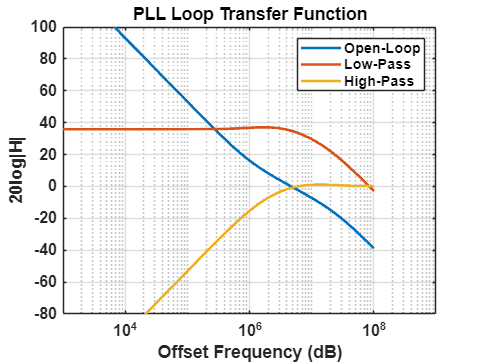

%Tp = (sec(PM)-tan(PM))/Wc; % Time constant of pole;
%Tz = 1/(Wc*Wc*Tp);
Tp = 1/(Wc*5);
Tz = 1/(Wc/5);
%Ctotal = Kpfdcp*Kvco/(N*Wc^2)*sqrt((1+(Wc*Tz)^2)/(1+(Wc*Tp)^2));
%C2 = Ctotal*Tp/Tz;
%C1 = Ctotal-C2;
%R1 = Tz/C1;
%Hlf = (1+Tz.*s)./(Ctotal .*(s.* (1 + Tp.*s) )); % 2nd-order loop filter in type-ii HMPLL
R1 = N.*Wc./(Kpfdcp.*Kvco);
C1 = a.*Kpfdcp.*Kvco./(N.*Wc.^2);
C2 = Kpfdcp .* Kvco ./(a.*N.*Wc.^2);
Hlf = (1+s.*R1.*C1)./(s.*(C1+C2)+R1.*C1.*C2.*s.^2);


Fout = Fref * N; %% Output Frequency
%Loop Filters

%Loop Transfer Functions
%Main PLL
Hopen2 = Kpfdcp .* Hlf .* (Kvco ./ s) .* (1/N);
Hopen2dB = 20 .* log10(abs(Hopen2));

Hclose2 = N .* Hopen2 ./ (1 + Hopen2);
Hclose2dB = 20 .* log10(abs(Hclose2));

Hvco2 = 1 ./ (1+Hopen2);
Hvco2dB = 20 .* log10(abs(Hvco2));

figure(1)
semilogx(f,Hopen2dB,f,Hclose2dB,f,Hvco2dB,'LineWidth',2);
set(gca, 'FontName', 'Arial', 'fontsize', 12, 'fontweight', 'b');
axis ([1e3 1e9 -80 100]);
grid on;
legend ('Open-Loop', 'Low-Pass', 'High-Pass');
xlabel('Offset Frequency (dB)');
ylabel('20log|H|');
title('PLL Loop Transfer Function');

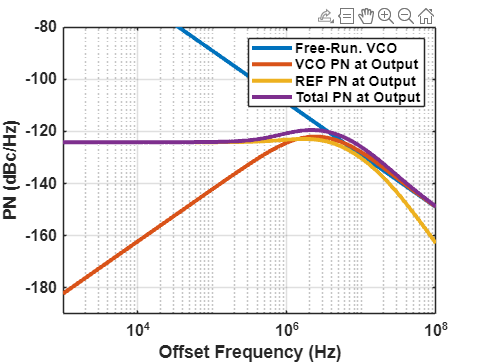


%Noise Sources
%HM PLL
n_psd_ref = 1e-16; % VDD=1.2, Vth = 0.4
n_psd_vco2 = 4.*pi.*k.*T.*(1+y) .* (Fout ./ 2 ./ Q ./f) .^2 ./ (P_vco.*1e-3);
%n_psd_dsm = ( ( (2 * pi) / N) ^ 2) .* (1 / 12) .* (1 / Fref) .* ( (2 .* sin(pi .* f ./ Fref) ) .^ (2 * (l-1) ) );

Svco2_Free_dB =  10 .* log10(n_psd_vco2);

%Output Noise
%Main PLL
Svco2 = (abs(Hvco2) .^ 2) .* n_psd_vco2;
Svco2dB = 10 .* log10(Svco2);

Sref = (abs(Hclose2) .^ 2) .* n_psd_ref;
SrefdB = 10 .* log10(Sref);

%Sdsm = (abs(Hclose2) .^ 2) .* n_psd_dsm;
%SdsmdB = 10 .* log10(Sdsm);

Stotal = Svco2 + Sref;
StotaldB = 10 .* log10(Stotal);

figure (2);
semilogx(f, Svco2_Free_dB,f,Svco2dB,f, SrefdB, f,StotaldB,  'LineWidth', 3);
set(gca, 'FontName', 'Arial', 'fontsize', 12, 'fontweight', 'b');
axis ([1e3 1e8 -190 -80]);
grid on;
legend ('Free-Run. VCO', 'VCO PN at Output', 'REF PN at Output', 'Total PN at Output');
xlabel('Offset Frequency (Hz)');
ylabel('PN (dBc/Hz)');

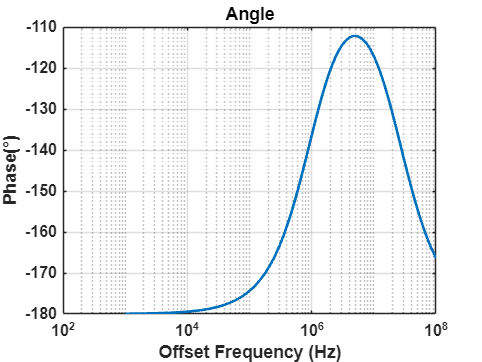


AngLoop = angle(Hopen2) .* 360 ./(2*pi)-360;
for n=1:length(AngLoop)
   
    if AngLoop(n) < -360
        AngLoop(n) = AngLoop(n) + 360;
    end
end

figure(3)
semilogx(f,AngLoop,'LineWidth',2);
set(gca, 'FontName', 'Arial', 'fontsize', 12, 'fontweight', 'b');
grid on;
xlabel('Offset Frequency (Hz)');
ylabel('Phase(°)');
title('Angle');


A = Stotal .* 1e3;
A_T = sum(A);
J = (sqrt(2 * A_T) ) / (2 * pi * Fout);
obj(1) = (sqrt(2 * A_T) ) / (2 * pi * Fout);
obj(2) = P_vco;

%display(strcat('Total Jitter =',32,num2str(J_Nest*1e15),32,'fs'));
%display(strcat('FOM =',32,num2str(objective),32));
